load('C:\Users\Asus\Desktop\data_B')

x=data_P6(1:1000,1:11);
y=data_P6(1:1000,12);
rng('default');
cv = cvpartition(size(x,1),'HoldOut',0.3);
idx = cv.test;
% Separate to training and test data
x_train = x(~idx,:);
x_test  = x(idx,:);
y_train = y(~idx,:);
y_test  = y(idx,:);  

teta_init=zeros(11,1);
p=100*eye(11);
% landa=0.1;
landa=0.97;
% landa=0.95;
% landa=0.99;

for i=1:700
    p = (p/landa) - ( p * x_train(i,:)' * x_train(i,:) * p) /(landa^2+landa*(x_train(i,:)*p*x_train(i,:)'));
    epsilon = y_train(i)-x_train(i,:)*teta_init;
    teta_init = teta_init + p*x_train(i,:)'*epsilon;
end

teta=teta_init;

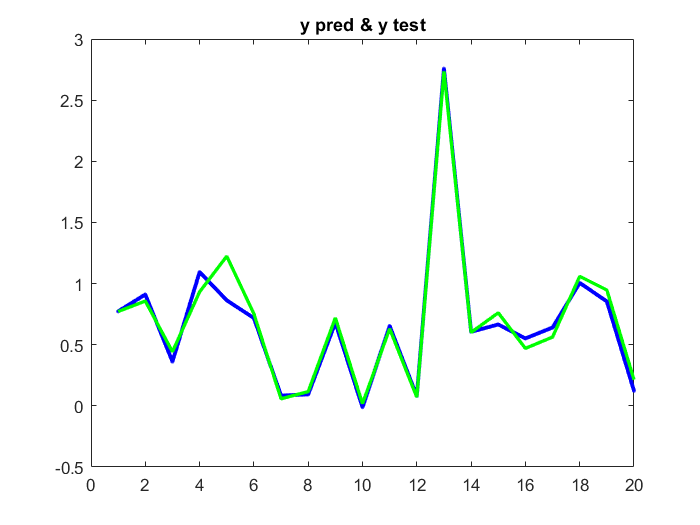

y_pred_train=x_train*teta;
   y_pred=x_test*teta;
   
   MSE = mean((y_pred - y_test).^2);
   MSE_test = MSE;
   
   MSE1 = mean((y_pred_train - y_train).^2);
   MSE_train = MSE1;
   
   errors =  y_test - y_pred;
   error_test=errors;
   
   errors1 =  y_train - y_pred_train;
   error_train=errors1;
   
   MAE = mean(abs(y_pred - y_test));
   MAE_test = MAE;

   MAE1 = mean((y_pred_train - y_train).^2);
   MAE_train = MAE1;
   
   
% subplot_rows = 3;
% subplot_cols = 4;
% 
%     % Generate the plot for the current i
% subplot(subplot_rows, subplot_cols, i);
u = x_test(:, 2);
cov_teta_hat = ((errors' * errors) * (x_train' * x_train)^-1)/(700-11);
errbar = sqrt(diag(x_test * cov_teta_hat * x_test'));






plot(y_pred(1:20,:),'.-b','linewidth',2.3);
hold on
plot(y_test(1:20,:),'-g','linewidth',2);
title("y pred & y test");
 hold off 

 
%  subplot(subplot_rows, subplot_cols, i);
% plot(y_pred,'.-b','linewidth',2.3);
% hold on
% plot(y_test,'-g','linewidth',2);
% title("y pred & y test");
%  hold off 
%  
 
 
 

ghodrat_noise=errors.'*errors/(700-11);
deghat_takhmin=cov(teta);
deghat_model=MSE;

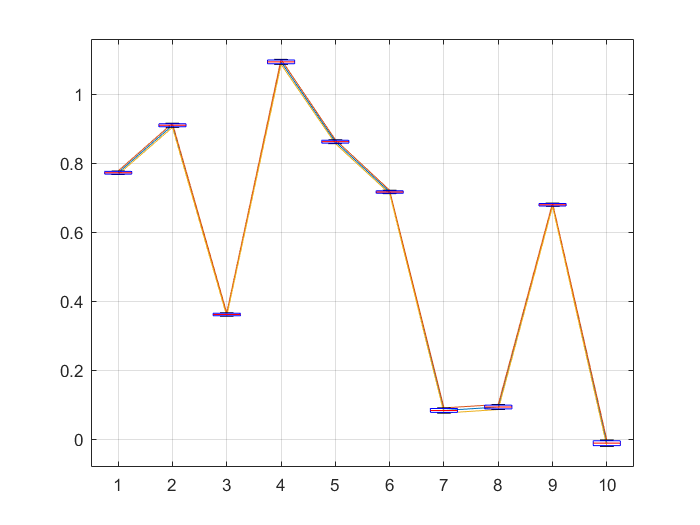

    
u1=1:1:10;
plot((y_pred(1:10,:)),'-');
hold on
plot((y_pred(1:10,:)+errbar(1:10,:)));
hold on
plot((y_pred(1:10,:)-errbar(1:10,:)));
grid

x=sort(u1).';
y=sort(y_pred(1:10,:)).';
data = [((y_pred(1:10,:))-errbar(1:10,:)).'; (y_pred(1:10,:)).'; ((y_pred(1:10,:))+errbar(1:10,:)).'];

% Add a box plot
boxplot(data, 'positions', x, 'widths', 0.5);
hold off

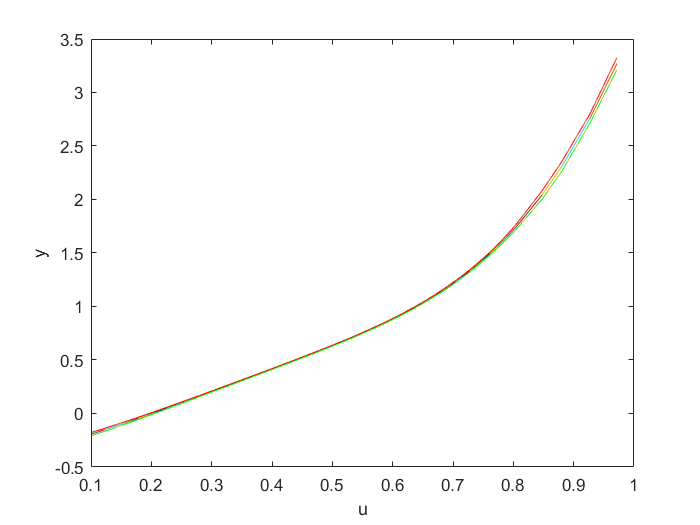

    upper_bound=y_pred + errbar;
    lower_bound=y_pred - errbar;
    
   [a_sorted, sort_idx] = sort(u);
b_sorted = y_pred(sort_idx);
c_sorted =upper_bound(sort_idx);
d_sorted =lower_bound(sort_idx);
% CI_low_sorted=CI_low(sort_idx)
% CI_high_sorted=CI_high(sort_idx)


plot(a_sorted, b_sorted, '-');
hold on;
plot(a_sorted, c_sorted, '-');
hold on
plot(a_sorted, d_sorted, '-');
hold on
% plot(a_sorted, CI_low_sorted, '-');
% hold on
% plot(a_sorted, CI_high_sorted, '-');
% hold on

for j = 1:length(a_sorted)-1
    x = [a_sorted(j), a_sorted(j+1)];
    y = [b_sorted(j), b_sorted(j+1)];
    plot(x, y);
    hold on
    xx = [a_sorted(j), a_sorted(j+1)];
    yy = [c_sorted(j), c_sorted(j+1)];
    plot(xx, yy, 'r--');
     hold on
    xxx = [a_sorted(j), a_sorted(j+1)];
    yyy = [d_sorted(j), d_sorted(j+1)];
    plot(xxx, yyy, 'g--');
%          hold on
%     xxxx = [a_sorted(j), a_sorted(j+1)];
%     yyyy = [CI_low_sorted(j), CI_low_sorted(j+1)];
%     plot(xxxx, yyyy, 'g--');
%          hold on
%     xxxxx = [a_sorted(j), a_sorted(j+1)];
%     yyyyy = [CI_high_sorted(j), CI_high_sorted(j+1)];
%     plot(xxxxx, yyyyy, 'g--');
end
    xlabel('u');
    ylabel('y');


    % Set subplot title

    hold off

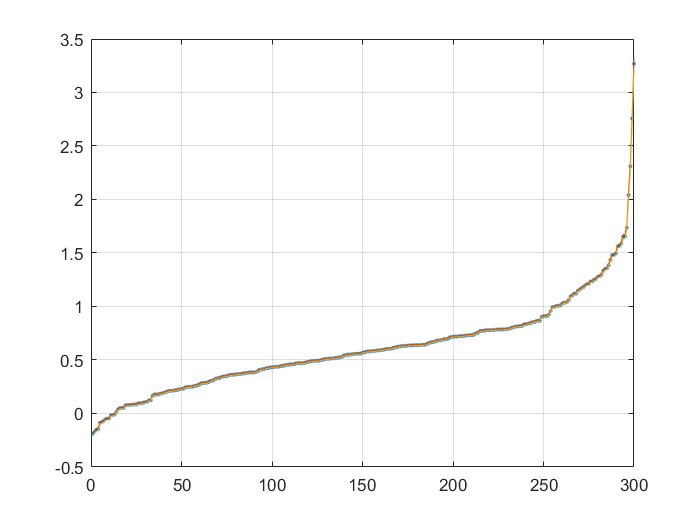

figure;
plot(sort(y_pred),'.');
hold on
plot(sort(y_pred+errbar));
hold on
plot(sort(y_pred-errbar));
grid

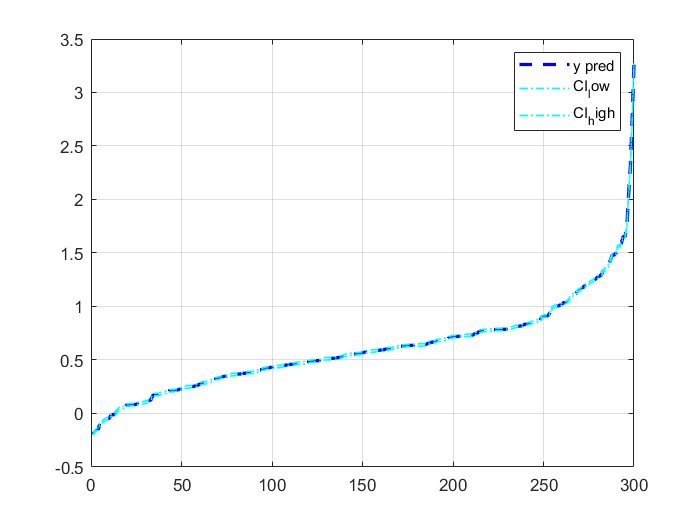

% Calculate the confidence interval
CI = 1.96 * std(errors) / sqrt(length(errors));
CI_low = y_pred - CI;
CI_high = y_pred + CI;

% Plot 
figure
plot(sort(y_pred), '--b', 'LineWidth', 2)
hold on
plot(sort(CI_low), '-.c', 'LineWidth', 1)
hold on
plot(sort(CI_high), '-.c', 'LineWidth', 1)
grid
legend('y pred', 'CI_low', 'CI_high')
hold off